# 4. Training Networks

load satData.mat % load the image and class labels

### Peek into the data

Note the dimensions of the data.

categories(YTrain) % View the class labels

ans = 6×1 cell 배열
    {'barren land'}
    {'building'   }
    {'grassland'  }
    {'road'       }
    {'trees'      }
    {'water'      }


size(XTrain) % View the dimensions of the training set of image data

ans =           28          28           4        3000


## Create a Network from Layers

### Create the CNN Layers

Create a column vector of 6 layers named `layers`, with the layers in the order shown below.

`imageInputLayer``(``inputSize``)`

`convolution2dLayer``(``filterSize``,``numFilters``)`

`reluLayer``()`

`maxPooling2dLayer``(``poolSize``)`

`fullyConnectedLayer``(``numClasses``)`

`softmaxLayer``()`

Use the following information to choose the inputs for the layers:

- Each image is size 28-by-28-by-4.

- The convolution layer should have a 20 filters of size 3-by-3.

- The pooling layer should have a pool size of 3-by-3.

- There are six classes.

layers = [imageInputLayer([28,28,4]); convolution2dLayer([3,3], 20);...
    reluLayer(); maxPooling2dLayer([3,3]);...
    fullyConnectedLayer(6); softmaxLayer()];

## Train the Network with Different Training Options

### Training Options

Create training options named `options`. 

- Use the algorithm `"sgdm"`,`"adam"` and `"rmsprop"`

- Set the maximum number of epochs to 5 to 100

- Set the minibatch size to 200

- Set the initial learning rate to 0.0001 and 0.001 (If you set 0.001, you will see `NaN` of Mini-batch Loss in the training-progress plot. How can you fix this without decreasing the initial learning rate? Use Gradient Clipping with `GradientThreshold` option.)

- Plot the training progress

options = trainingOptions("adam","MaxEpochs",50,...
    "InitialLearnRate",0.0001,"MiniBatchSize",128,...
    "Plots","training-progress","Metrics","accuracy");

### Train the Network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingAccuracy
    _________    _____    ___________    _________    ____________    ________________
            1        1       00:00:00       0.0001          12.575              13.281
           50        3       00:00:04       0.0001          1.2017              83.594
          100        5       00:00:06       0.0001         0.76795              92.188
          150        7       00:00:07       0.0001         0.49059              91.406
          200        9       00:00:09       0.0001         0.25078              94.531
          250       11       00:00:10       0.0001         0.49164              90.625
          300       14       00:00:12       0.0001         0.55633              89.062
          350       16       00:00:13       0.0001         0.73422              90.625
          400       18       00:00:14       0.0001         0.38841              92.969
          450       20       00:00:15      

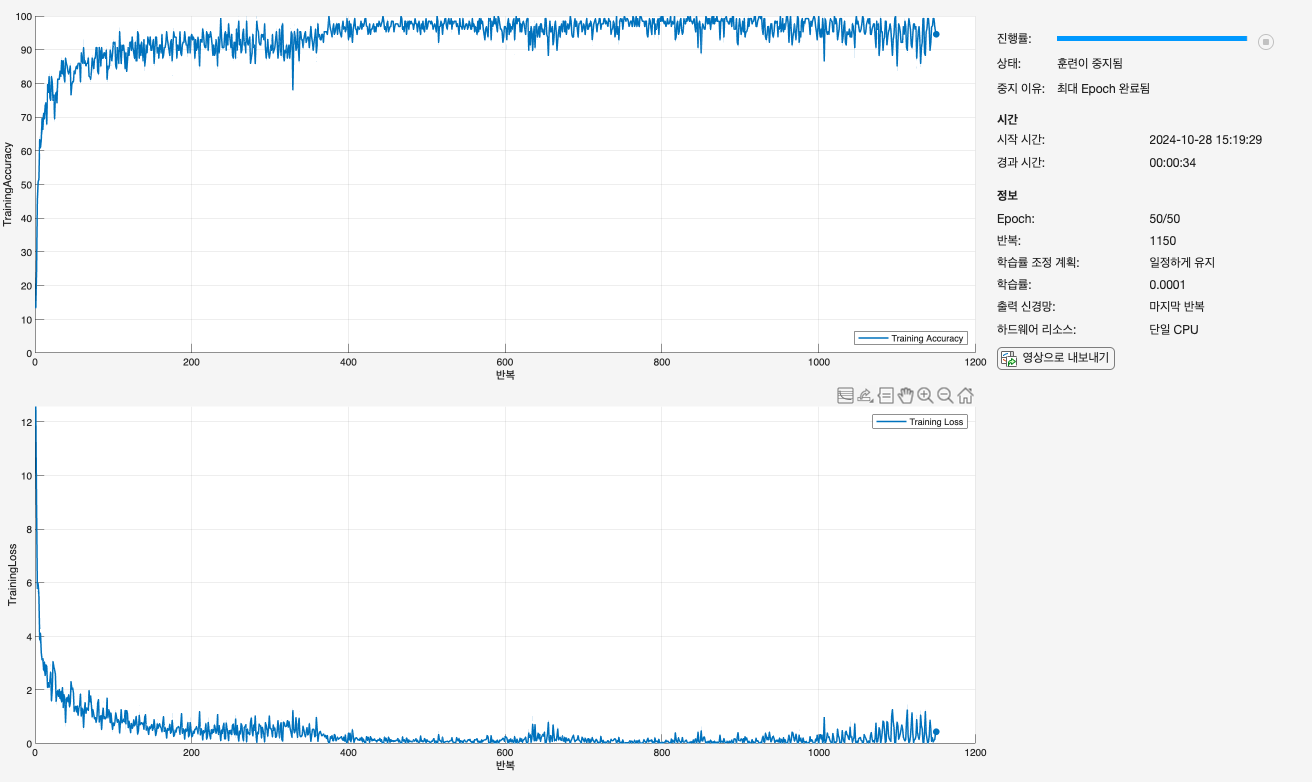

landnet = trainnet(XTrain,YTrain,layers,"crossentropy",options);

### Classify and Evaluate the Network

classes = categories(YTest);
scores = minibatchpredict(landnet,XTest); % Prediction by the network
[testPred, score] = scores2label(scores,classes);
testAcc = nnz(testPred == YTest) / numel(testPred)

testAcc = 0.9117

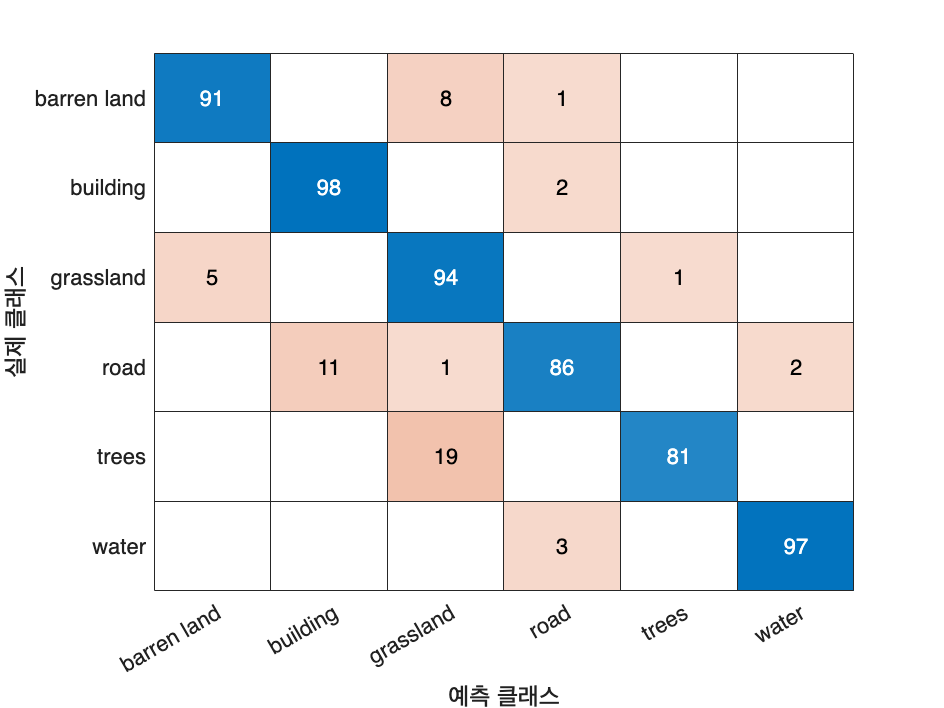

confusionchart(YTest,testPred) % Visualization in a confusion matrix

## Validation Data Set

To prevent overfitting, you can use a validation data set. If the validation accuracy is consistently lower than the training accuracy, you can stop the training.

valData = {XVal YVal}

valData = 1×2 cell 배열
    {28×28×4×600 uint8}    {600×1 categorical}


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:00       0.0001                            13.747                                    8.3333
            1        1       00:00:00       0.0001          14.165                                7.8125                      
           10        1       00:00:03       0.0001          4.2866             4.656              64.062                    60
           20        1       00:00:03       0.0001          4.2641            3.1328              67.969                72.667
           30        2       00:00:04       0.0001           4.023            2.0799              71.094                80.833
           40        2       00:00:04       0.0001          2.8636            3.5137              76.562       

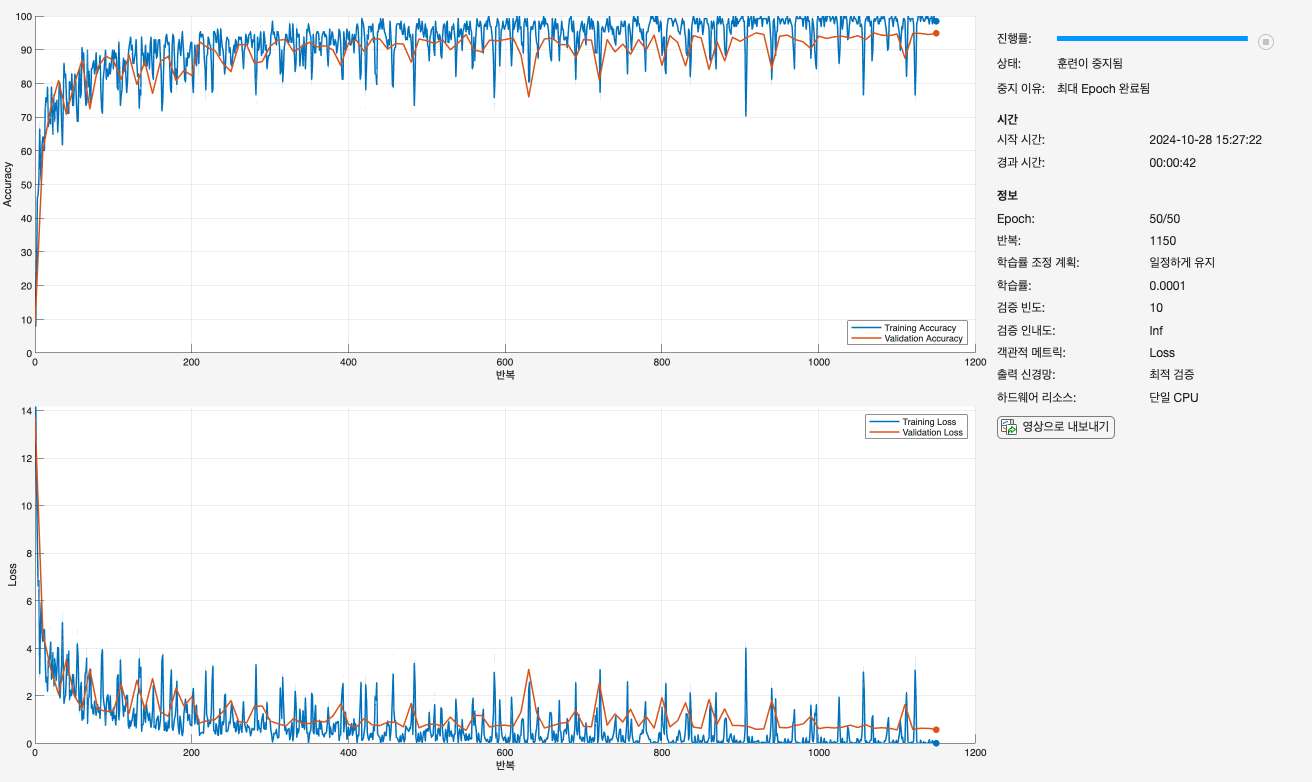

options = trainingOptions("rmsprop", "MaxEpochs",50,...
    "MiniBatchSize",128,"InitialLearnRate",0.0001,...
    "Plots","training-progress","Metrics","accuracy",...
    "ValidationData",valData,"ValidationFrequency",10,...
    "OutputNetwork","best-validation");


landnet = trainnet(XTrain,YTrain,layers,"crossentropy",options);

classes = categories(YTest);
scores = minibatchpredict(landnet,XTest); % Prediction by the network
[testPred, score] = scores2label(scores,classes);
testAcc = nnz(testPred == YTest) / numel(testPred)

testAcc = 0.9233

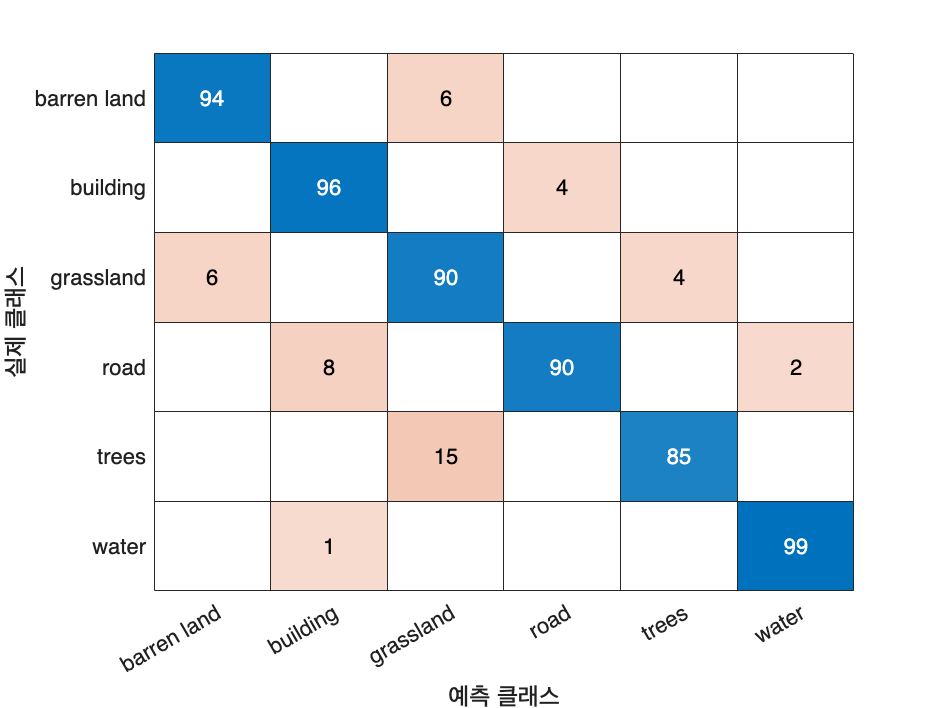

confusionchart(YTest,testPred) % Visualization in a confusion matrix